# Assignment 13

# **Joint assimilation of navigation data coming from different sources**  

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

#### **Part I. Assimilation of GPS data only (absolute positioning)**

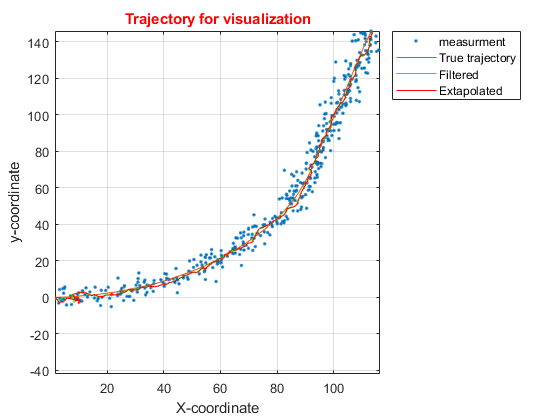

clc; clear 
load('theta.mat');  % load data
n = 500;            % size of trajectory
m = 1;              % steps for extrapolation

% Crating Arrays to save the values of Errors over 500 runs. 
XF_Err = ones(500,n); XF_E = ones(1,n);         % filteration error for position X
YF_Err = ones(500,n); YF_E = ones(1,n);         % filteration error for position Y
XP_Err = ones(500,n); XP_E = ones(1,n);         % error in covariance matrix P for X
YP_Err = ones(500,n); YP_E = ones(1,n);         % error in covariance matrix P for Y
XE_Err = ones(500,n-m); XE_E = ones(1,n-m);     % extrapolation error in position X
YE_Err = ones(500,n-m); YE_E = ones(1,n-m);     % extrapolation error in position Y

% run for 500 times
for j = 1:500
    N = length(theta);
    T = 0.05;           % time step
    x = zeros(1,N);     
    y = zeros(1,N);
    sigma_z = 3;        % SD of measurment noise
    sigma_a = 5;        % SD of noise used for calculatin Q matrix
    v = 10;             % initial velocity
    zx = zeros(1,N); zx(1) = normrnd(0,sigma_z);        % vector to save X postition measurments  
    zy = zeros(1,N); zy(1) = normrnd(0,sigma_z);        % vector to save Y postition measurments
    
    % creating trajectory & measurments
    for i = 2:N
        x(i) = x(i-1)+v*cos(theta(i-1))*T+0.5*T*normrnd(0,1);
        y(i) = y(i-1)+v*sin(theta(i-1))*T+0.5*T*normrnd(0,1);
        zx(i) = x(i)+normrnd(0,sigma_z);
        zy(i) = y(i)+normrnd(0,sigma_z);
    end
    
    % plot(x,y,zx,zy,'*')
    XF = zeros(4,N);
    XE = zeros(4,N);
    X0 = [zx(2); (zx(2)-zx(1))/T; zy(2); (zy(2)-zy(1))/T];  % initial filtered estimate of state vector
    phi = [1 T 0 0; 0 1 0 0; 0 0 1 T; 0 0 0 1];             % transition matrix
    G = [(T^2)/2 0; T 0; 0 (T^2)/2; 0 T];                   % input matrix
    H = [1 0 0 0; 0 0 1 0];                                 % observation matrix
    Q = G*G'.*sigma_a^2;                                    % covariance matrix of state noise 
    P = diag([10^4 10^4 10^4 10^4 ]);                       % initial filtration error covariance matrix
    R = [sigma_z^2 0; 0 sigma_z^2];                         % measurement noise covariance matrix
    K = P*H'/(H*P*H'+R);                                    % initial value of filter gain
    
    % run kalam filter 
    for i = 3:N
        Z = [zx(i); zy(i)];
        
        % prediction
        Xp = phi*X0;
        Pex = phi*P*phi'+Q;
        
        % filteration 
        Xf = Xp+K*(Z-H*Xp);
        K = Pex*H'/(H*Pex*H'+R);
        P = (eye(4)-K*H)*Pex;
        
        % extrapolation 1 step forward
        Xe = phi*Xf;  
        
        XF(:,i) = Xf;
        XE(:,i) = Xe;

        X0 = Xf;
        % Errors Calculation. 
        XF_Err(j,i) = (x(i)-Xf(1))^2; 
        YF_Err(j,i) = (y(i)-Xf(3))^2; 
        XP_Err(j,i) = sqrt(P(1,1)); 
        YP_Err(j,i) = sqrt(P(3,3));
        if i<N
            XE_Err(j,i) = (x(i+1)-Xe(1))^2;
            YE_Err(j,i) = (y(i+1)-Xe(3))^2;
        end
    end
    
end 

for i = 3:N
   XF_E(i) = sqrt((1/499)*sum(XF_Err(:,i)));        % true filteration error for position X
   YF_E(i) = sqrt((1/499)*sum(YF_Err(:,i)));        % true filteration error for position Y
   XP_E(i) = (1/499)*sum(XP_Err(:,i));              % error of claculation for position X
   YP_E(i) = (1/499)*sum(YP_Err(:,i));              % error of calculation for position Y
   if i<N
       XE_E(i) = sqrt((1/499)*sum(XE_Err(:,i)));    % true extrapolation error for position X
       YE_E(i) = sqrt((1/499)*sum(YE_Err(:,i)));    % true extrapolation error for position Y
   end
end 

% plot
figure(1)
plot(zx,zy,'.',x,y,XF(1,:),XF(3,:),'g',XE(1,:),XE(3,:),'r')
title('Figure(1) Trajectory for visualization','color','r')
xlabel('X-coordinate')
ylabel('y-coordinate')
legend('measurment','True trajectory','Filtered','Extapolated','location','northeastoutside')
grid on

**Comment:**

In the figure above, the true trajectory, the measurements, the Kalman filter estimation and extapolation with 1-step  ahead are graphed against each other. It can be seen that the estimation values are kind of following the trajectory with some disturbances.

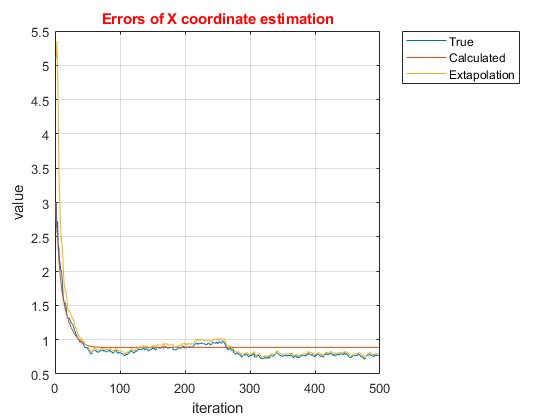

figure(2)
plot(1:500-2,XF_E(3:end),1:500-2,XP_E(3:end));
hold on 
plot(2:500-2,XE_E(3:end));
hold off 
title('Figure(2) Errors of X coordinate estimation','color','r')
xlabel('iteration')
ylabel('value')
legend('True','Calculated','Extapolation','location','northeastoutside')
grid on

**Comment:**

In figure 2 above, true estimation errors of filteration and extrapolation are clearly approacing the calculated error at the beginning then settles at a value of ~7.6, slightly lower that the caluclatrd error of 0.88. The filter is quite effictive wth this small errors. 

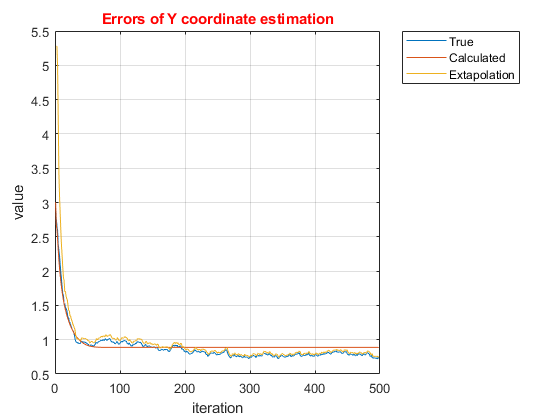

figure()
plot(1:500-2,YF_E(3:end),1:500-2,YP_E(3:end));
hold on 
plot(2:500-2,YE_E(3:end));
hold off 
title('Figure(3) Errors of Y coordinate estimation','color','r')
xlabel('iteration')
ylabel('value')
legend('True','Calculated','Extapolation','location','northeastoutside')
grid on

**Comment:** 

Similar to figure 2, In figure 3 above, true estimation errors of filteration and extrapolation are clearly approacing the calculated error at the beginning then settles at a value of ~7.9, slightly lower that the caluclatrd error of 0.88. The filter is quite effictive wth this small errors. 

#### Part II. Assimilation of both GPS data (absolute positioning) and wheel odometry data (relative positioning).

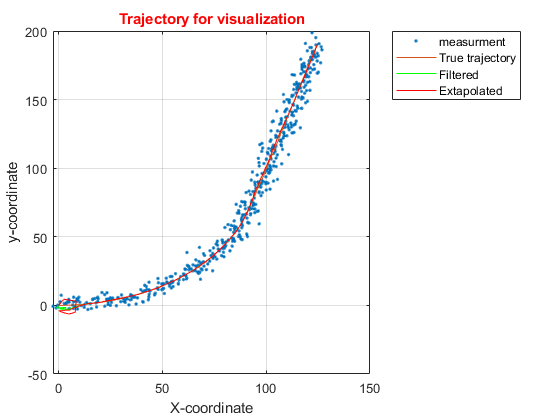

clc ; clear 
load('theta.mat');      % load data
n=500;                  % size of trajectory
m=1;                    % steps for extrapolation

% Crating Arrays to save the values of Errors over 500 runs. 
XF_Err=ones(500,n); XF_E=ones(1,n);             % filteration error for position X
YF_Err=ones(500,n); YF_E=ones(1,n);             % filteration error for position Y
XP_Err=ones(500,n); XP_E=ones(1,n);             % error in covariance matrix P for X
YP_Err=ones(500,n); YP_E=ones(1,n);             % error in covariance matrix P for Y
XE_Err=ones(500,n-m); XE_E=ones(1,n-m);         % extrapolation error in position X
YE_Err=ones(500,n-m); YE_E=ones(1,n-m);         % extrapolation error in position Y

% run for 500 times
for j=1:500
    N=length(theta);
    T=0.05;           % time step
    x=zeros(1,N);
    y=zeros(1,N);
    sigma_z=3;        % SD of measurment noise
    sigma_a=5;        % SD of noise used for calculatin Q matrix
    sigma_v=0.5;      
    sigma_th=0.05;
    v=10;             % initial velocity
    vm=zeros(1,N); vm(1)=v+normrnd(0,sigma_v);
    zx=zeros(1,N); zx(1)=normrnd(0,sigma_z);
    zy=zeros(1,N); zy(1)=normrnd(0,sigma_z);
    theta_m=zeros(1,N);theta_m(1)=theta(1)+normrnd(0,sigma_th);
    
    for i=2:N
        x(i)=x(i-1)+v*cos(theta(i-1))*T+0.5*T*normrnd(0,1);
        y(i)=y(i-1)+v*sin(theta(i-1))*T+0.5*T*normrnd(0,1);
        vm(i)=v+normrnd(0,sigma_v);
        theta_m(i)=theta(i)+normrnd(0,sigma_th);
        zx(i)=x(i)+normrnd(0,sigma_z);
        zy(i)=y(i)+normrnd(0,sigma_z);
    end
    
    % plot(x,y,zx,zy,'*')
    XF=zeros(4,N);
    XE=zeros(4,N);
    X0=[zx(2);(zx(2)-zx(1))/T; zy(2); (zy(2)-zy(1))/T];
    phi=[1 T 0 0; 0 1 0 0; 0 0 1 T; 0 0 0 1];
    G=[(T^2)/2 0; T 0; 0 (T^2)/2; 0 T];
    H=[1 0 0 0; 0 0 1 0];
    Q=G*G'.*sigma_a^2;
    P=diag([10^4 10^4 10^4 10^4 ]);
    R=diag([sigma_z^2 sigma_z^2 sigma_v^2 sigma_th^2 ]);
    dH=getdH(X0);
    K=P*dH'/(dH*P*dH'+R);
    for i=3:N
        Z=[zx(i);
           zy(i);
           vm(i);
           theta_m(i)];
        Xp=phi*X0;
        H=getH(Xp);
        Pex=phi*P*phi'+Q;
        Xf=Xp+K*(Z-H);
        Xe=phi*Xf;
        XF(:,i)=Xf;
        XE(:,i)=Xe;
        dH=getdH(Xp);
        K=Pex*dH'/(dH*Pex*dH'+R);
        P=(eye(4)-K*dH)*Pex;
        X0=Xf;
        
        % Errors Calculation. 
        XF_Err(j,i)=(x(i)-Xf(1))^2;
        YF_Err(j,i)=(y(i)-Xf(3))^2; 
        XP_Err(j,i)=sqrt(P(1,1)); 
        YP_Err(j,i)=sqrt(P(3,3));
        if i<N
            XE_Err(j,i)=(x(i+1)-Xe(1))^2;
            YE_Err(j,i)=(y(i+1)-Xe(3))^2;
        end
    end
    
end 

for i=3:N
   XF_E(i)=sqrt((1/499)*sum(XF_Err(:,i))); 
   YF_E(i)=sqrt((1/499)*sum(YF_Err(:,i)));
   XP_E(i)=(1/499)*sum(XP_Err(:,i)); 
   YP_E(i)=(1/499)*sum(YP_Err(:,i)); 
   if i<N
       XE_E(i)=sqrt((1/499)*sum(XE_Err(:,i))); 
       YE_E(i)=sqrt((1/499)*sum(YE_Err(:,i))); 
   end
end 

figure(4)
plot(zx,zy,'.',x,y,XF(1,:),XF(3,:),'g',XE(1,:),XE(3,:),'r')
title('Figure(4) Trajectory for visualization','color','r')
xlabel('X-coordinate')
ylabel('y-coordinate')
legend('measurment','True trajectory','Filtered','Extapolated','location','northeastoutside')
grid on

**Comment:**

In the figure above, the true trajectory, the measurements, the Kalman filter estimation and extapolation with 1-step  ahead are graphed against each other. It can be seen that the estimation values are kind of following the trajectory with some disturbances.

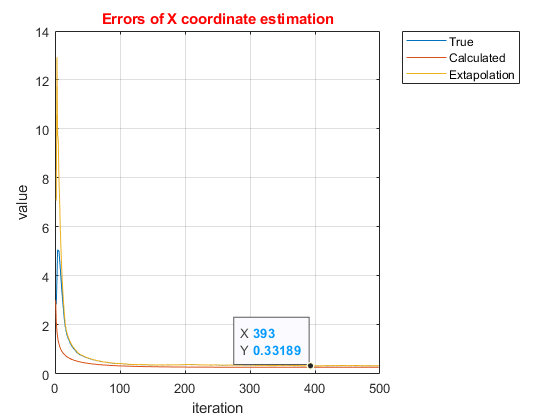

figure(5)
plot(1:500-2,XF_E(3:end),1:500-2,XP_E(3:end));
hold on 
plot(2:500-2,XE_E(3:end));
hold off 
title('Figure(5) Errors of X coordinate estimation','color','r')
xlabel('iteration')
ylabel('value')
legend('True','Calculated','Extapolation','location','northeastoutside')
grid on

**Comment:**

In figure 5 above, true estimation errors of filteration and extrapolation are clearly approacing the calculated error with a little shift. Estimation errors approach a value if 0.33, slighlty higher than the calulculated error, but much lower compared to the previous case with GPS data only. This proves that the odometry data were more accurate and closer to the true trajectory and thus relying on both data reslted in much better results. 

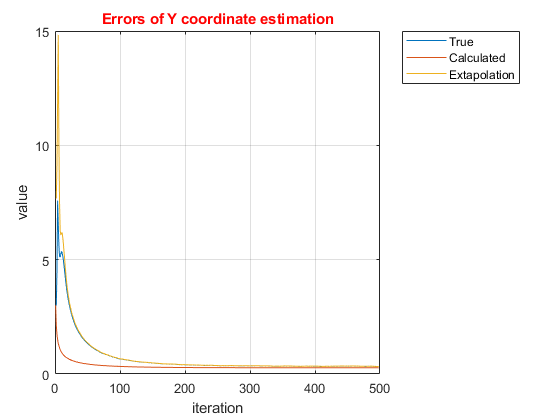

figure(6)
plot(1:500-2,YF_E(3:end),1:500-2,YP_E(3:end));
hold on 
plot(2:500-2,YE_E(3:end));
hold off 
title('Figure(6) Errors of Y coordinate estimation','color','r')
xlabel('iteration')
ylabel('value')
legend('True','Calculated','Extapolation','location','northeastoutside')
grid on

**Comment:**

similar to figure5, In figure 6 above, true estimation errors of filteration and extrapolation are clearly approacing the calculated error with a little shift. Estimation errors approach a value if 0.34, slighlty higher than the calulculated error, but much lower compared to the previous case with GPS data only. This proves that the odometry data were more accurate and closer to the true trajectory and thus relying on both data reslted in much better results. 

function [H]=getH(X)
 H=[X(1);
    X(3);
    sqrt(X(2)^2+X(4)^2);
    atan2(X(4),X(2))]; 
end

function [dH]=getdH(X)
 dH=[1 0 0 0; 
     0 0 1 0; 
     0 X(2)/sqrt(X(2)^2+X(4)^2) 0 X(4)/sqrt(X(2)^2+X(4)^2);
     0 -X(4)/(X(2)^2+X(4)^2) 0 X(2)/(X(2)^2+X(4)^2)];
end

# Learning Log:

In this assignment we develop a navigation filter by assimilating data coming from different sources at the same time using nonlinear model (Extended Kalman filter). Eventually we summarized what we learnt in the following:

Finally, in real applications it is much better not to put all of our trust in a single sensor as it might not work properly at some point, or get affected by some eviromental factors. But too use multiple sensors(observers) and fusing their observations giving them different weights dependng on how much we trust each one.